# 01. Introduction

clear all; 
close all;
load assignment1.mat;

The code can be run by sections independamendly of each other except indication.

# 02. Bandwidth of Speech

clear all; 
close all;

Fs = 44100;
[m_y,~] = audioread('male44.wav');
[f_y,~] = audioread('female44.wav');

fc = 500;

f_LP = lowpass(f_y, fc/Fs);
soundsc(f_LP, Fs);
% Quote = "Simplest method is to mix the medicine with butter or some other grease and smear it on the nose of the animal from time to time"
pause(7);

m_LP = lowpass(m_y, fc/Fs);
soundsc(m_LP, Fs);
% Quote = "I rode for a long distance in one of the public coaches on the day preceding Christmas"
pause(5);

% man = sprintf("filteredVoice_m_%dHz.wav", fc);
% woman = sprintf("filteredVoice_f_%dHz.wav", fc);
% audiowrite(char(man),m_LP,Fs);
% audiowrite(char(woman),f_LP,Fs);



`[2.1] Determine cut-off frequency? fc = 2500 Hz`

`[2.2] Determine cut-off frequency for overall degradation? fc = 1000 Hz`

`[2.3] Frequency of 8 KHz were used because human speech is almost perfectly recognisable at the frequency of 4 KHz. `

# 3. Voiced and Unvoiced Speech Sounds

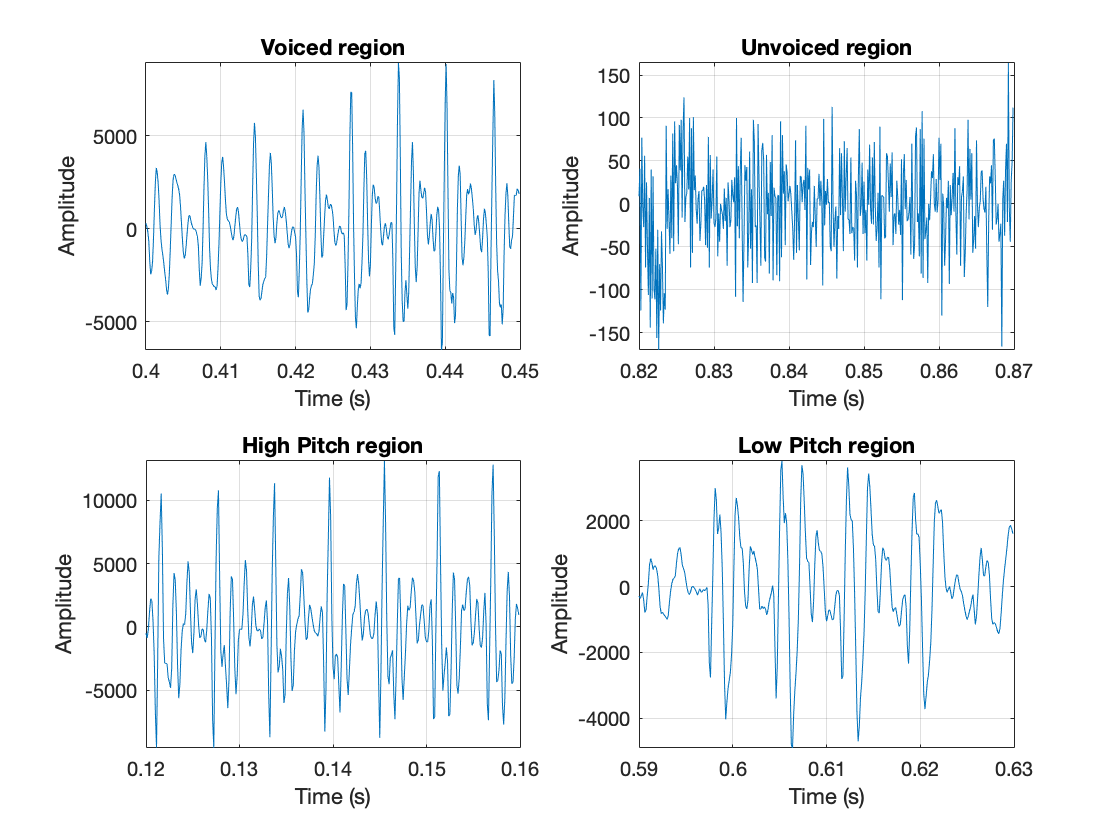

clear all; 
close all;
load assignment1.mat;

%soundsc(male_short)
Fs = 8000;
time = 0:1/Fs:size(male_short,1)/Fs - 1/Fs;

% subplot(2,1,1)
% f1 = figure(1); plot(time, male_short);
% grid on; xlabel('Time (s)'); ylabel('Amplitude');
% title('Time plot with voiced & unvoiced regions marked')

% subplot(2,1,2)
% plot(time, male_short);
% grid on; xlabel('Time (s)'); ylabel('Amplitude');
% title('Time plot with high and low pitch regions marked');

% A voiced sound correspond to a signal with a certain periodicity
% An unvoiced sound correspond to a noise signal
% A high pitch corrspond to a signal with a "high" frequency 
% A low pitch corrspond to a signal with a "low" frequency 

%Voice
subplot(2,2,1)
plot(time(0.4*Fs:0.45*Fs), male_short(0.4*Fs:0.45*Fs));
grid on; xlabel('Time (s)'); ylabel('Amplitude');
title('Voiced region')
axis([0.4 0.45 min(male_short(0.4*Fs:0.45*Fs)) max(male_short(0.4*Fs:0.45*Fs))])

%Unvoice
subplot(2,2,2)
plot(time(0.82*Fs:0.87*Fs), male_short(0.82*Fs:0.87*Fs));
grid on; xlabel('Time (s)'); ylabel('Amplitude');
title('Unvoiced region')
axis([0.82 0.87 min(male_short(0.82*Fs:0.87*Fs)) max(male_short(0.82*Fs:0.87*Fs))])

%High Pitch
subplot(2,2,3)
plot(time(0.12*Fs:0.16*Fs), male_short(0.12*Fs:0.16*Fs));
grid on; xlabel('Time (s)'); ylabel('Amplitude');
title('High Pitch region')
axis([0.12 0.16 min(male_short(0.12*Fs:0.16*Fs)) max(male_short(0.12*Fs:0.16*Fs))])

%Low Pitch
subplot(2,2,4)
plot(time(0.59*Fs:0.63*Fs), male_short(0.59*Fs:0.63*Fs));
grid on; xlabel('Time (s)'); ylabel('Amplitude');
title('Low Pitch region')
axis([0.59 0.63 min(male_short(0.59*Fs:0.63*Fs)) max(male_short(0.59*Fs:0.63*Fs))])

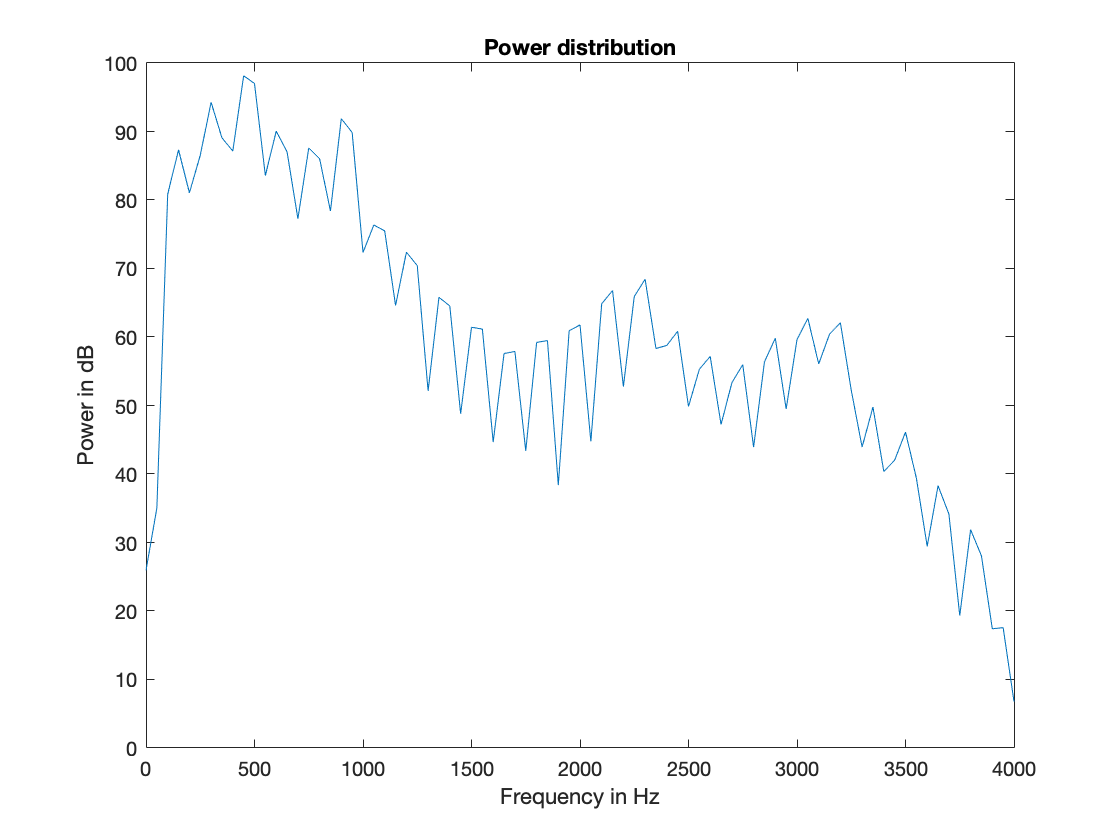

%[3.3] DFT based spectrum

% voice region between 0.4s and 0.52s

x = male_short; N = length(time(0.4*Fs:0.42*Fs)) - 1; S = 0.4*Fs;
% x is a vector of speech, N is the frame length (must be even)
% S is the first sample of the frame to be analyzed
xf = x(S:S+N-1).*hanning(N);
f = Fs*(0:(N/2))/N;
X = fft(xf);
figure(1); clf;
plot(f, 10*log10(abs(X(1:N/2+1)).^2));
title('Power distribution'); xlabel('Frequency in Hz'); ylabel('Power in dB'); %DFT(male_short, 1, size(male_short,1))

%[3.4] Expression for X[3]. It corresponds to frequency Fs*(3-1)/N Hertz. 
% In our exemple X(3) = 100 Hz

$X\left\lbrack 3\right\rbrack =\sum_{n=0}^{N-1} x\left\lbrack n\right\rbrack *w\left\lbrack n\right\rbrack \cdot W_N^{3n}$  ---> with x[n], the frame and w[n] the window

[3.5] Fundamental frequency = 500 Hertz (Approximation)

[3.6] When we use a small frame length we loose on frequency resoltion. If we use a large frame we cannot use the fact that the signal is stationary, indeed in a speech signal the statistic of a signal depend on the time. So we have to choose a frame length that allow us to have a good resolution and to "keep" the signal stationary.

A frame length about 20ms seems to be a good compromise.

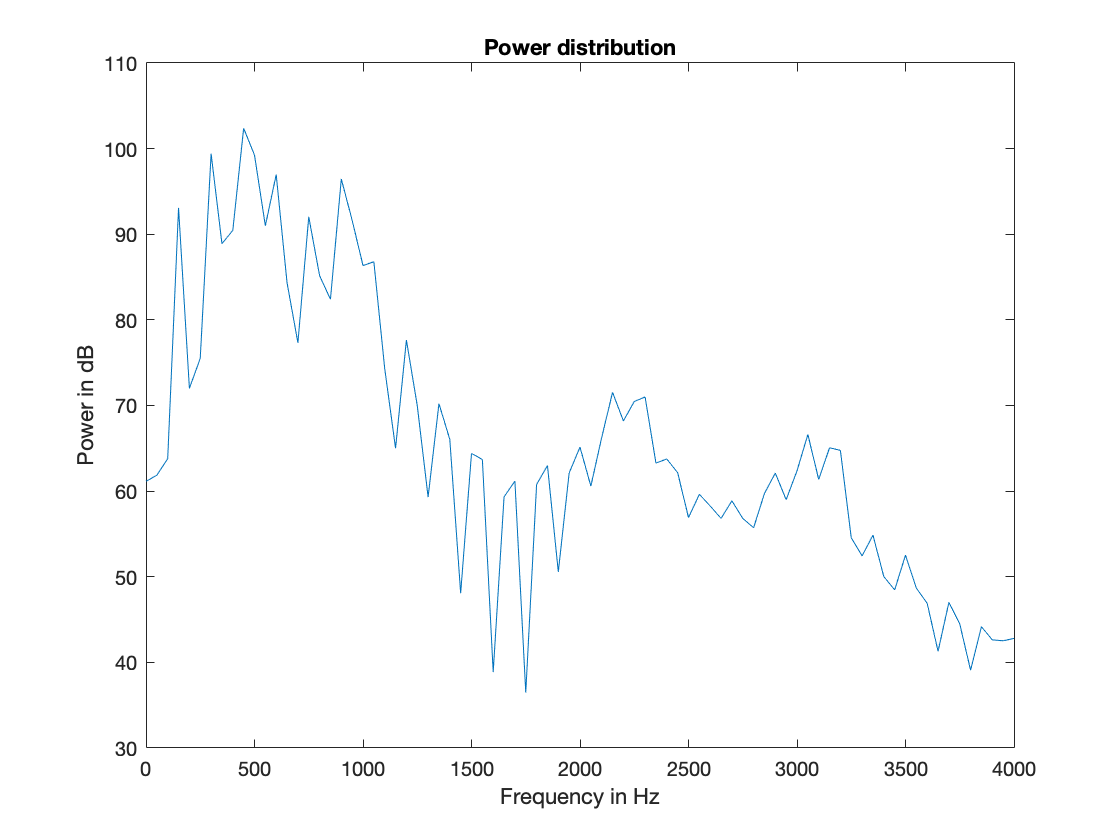

%[3.7] We replace the hanning window by a rectangular window

x = male_short; N = length(time(0.4*Fs:0.42*Fs)) - 1; S = 0.4*Fs;
% x is a vector of speech, N is the frame length (must be even)
% S is the first sample of the frame to be analyzed
xf = x(S:S+N-1).*rectwin(N);
%xf = x(S:S+N-1).*hanning(N);
f = Fs*(0:(N/2))/N;
X = fft(xf);
figure(1); clf;
plot(f, 10*log10(abs(X(1:N/2+1)).^2));
title('Power distribution'); xlabel('Frequency in Hz'); ylabel('Power in dB');

We can see that with a we have a better frequency resolution but we also have a big variance.

The choice of the window depend on the application and we have to make a compromise between resolution and variance.

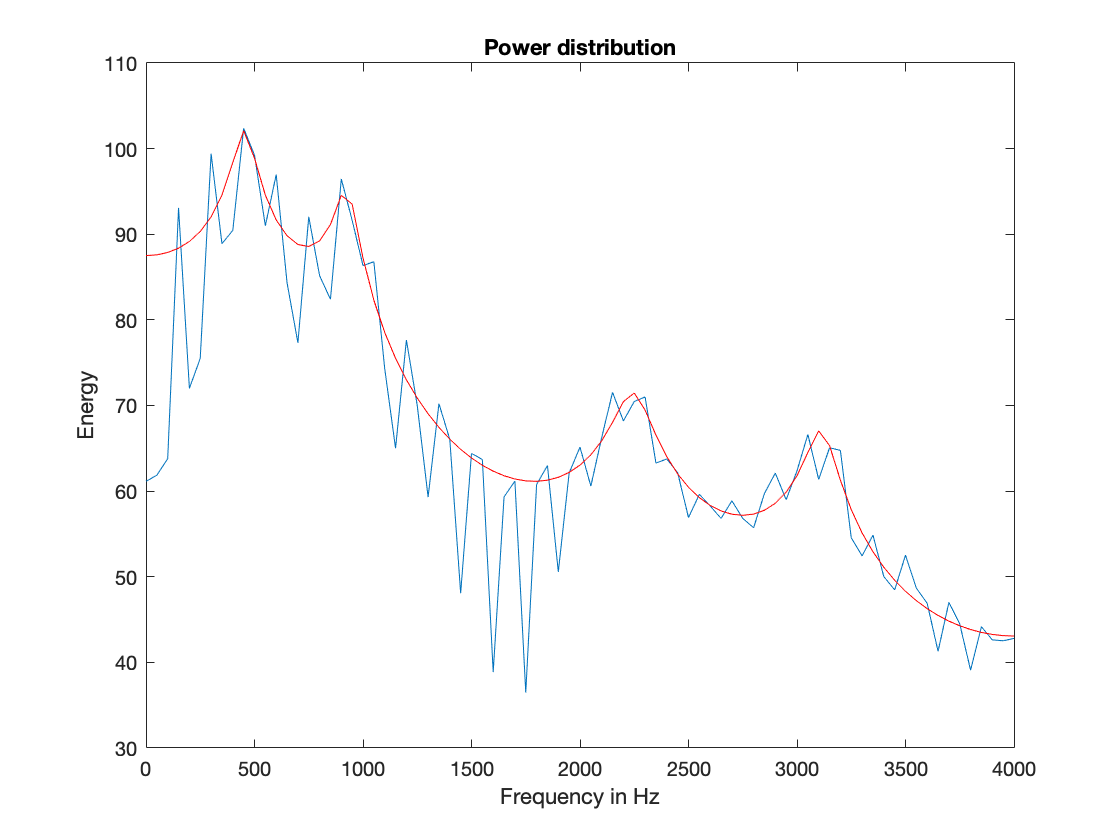

%[3.8] We try to predict the spectrum by using an AR model

% M is the prediction order
M = 10;
c = xcorr(xf, xf, M);
[a, e]= levinson(c(M+1:2*M+1)); % a is a vector always starting with a 1.
a = a(:); % Make a a column vector
% The commented code below is essentially equivalent to the twolines above
% r = c(M+1:2*M+1);
% R = toeplitz(r(1:M),r(1:M)); % A Toeplitz matrix with first row r(1:M)
% a = - R / r(2:M+1);
% a = [1; a]; % Add the leading 1
% e = sum(a*r);
h = zeros(N,1);
for k=0:N-1
    h(k+1) = 1 / (a'*exp(-1i*2*pi*k/N*(0:M)') );
end
% h = freqz(1, a, N, ’whole’); % Equivalent to the above for-loop! hold on
plot(f, 10*log10(abs(X(1:N/2+1)).^2)); hold on;
plot(f, 10*log10(e*abs(h(1:N/2+1)).^2), 'r');
title('Power distribution'); xlabel('Frequency in Hz'); ylabel('Energy');

[3.9] c(3) = $\sum_{n=0}^N x\left\lbrack n+3\right\rbrack *x\left\lbrack n\right\rbrack$

[3.10] By observing the power spectrum estimate we can see that there is 4 pics, that meens we can modelize the system by an AR-8 model (8 conjugate poles).

We multiply abs(h(1:N/2+1)) by e because the AR process is derived from a white noise of power e.

$\Phi_{output}(\Omega) = |H(\Omega)|^2 * \Phi_{input} = |H(\Omega)|^2 * \sigma^2$ for an AR-process.

We choose M = 10 to include all type of voice of people

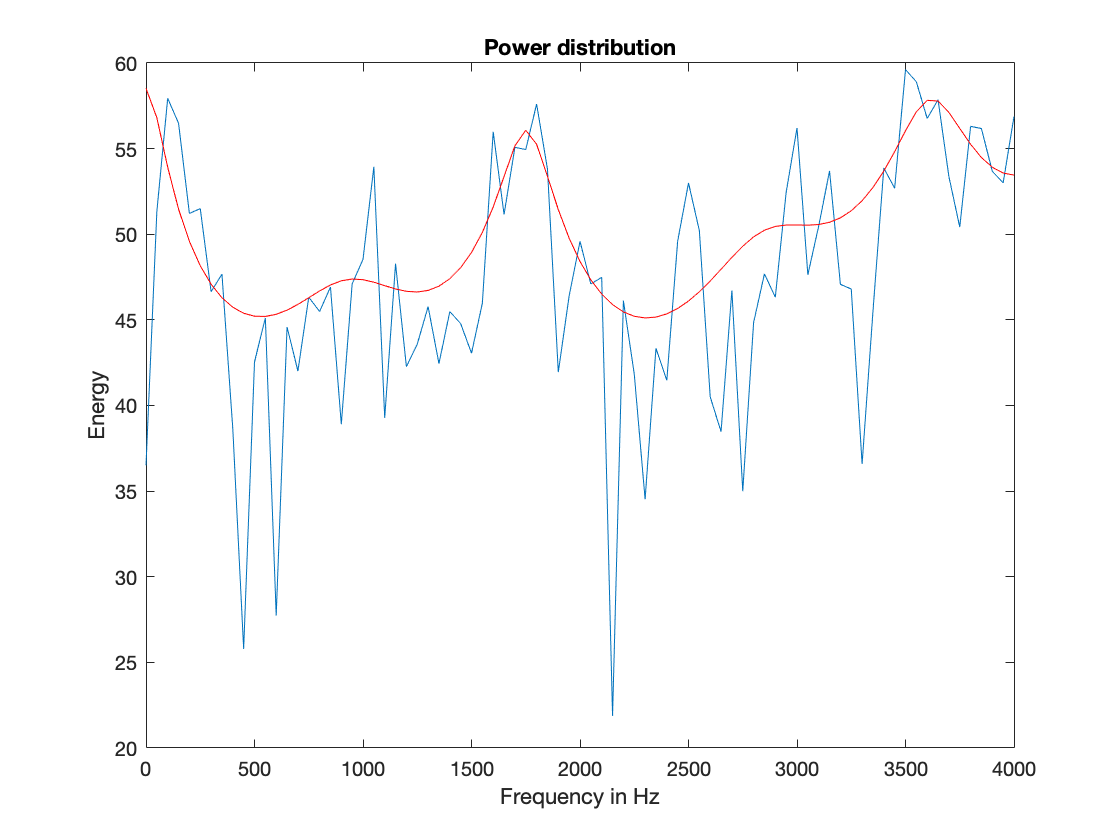

%[3.11] We repeate the process with an unvoiced sound

% unvoice region between 0.82s and 0.89s

x = male_short; N = length(time(0.82*Fs:0.84*Fs)) - 1; S = 0.82*Fs;
% x is a vector of speech, N is the frame length (must be even)
% S is the first sample of the frame to be analyzed
xf = x(S:S+N-1).*hanning(N);
%xf = x(S:S+N-1).*rectwin(N);
f = Fs*(0:(N/2))/N;
X = fft(xf);

% M is the prediction order
M = 10;
c = xcorr(xf, xf, M);
[a, e]= levinson(c(M+1:2*M+1)); % a is a vector always starting with a 1.
a = a(:); % Make a a column vector
% The commented code below is essentially equivalent to the twolines above
% r = c(M+1:2*M+1);
% R = toeplitz(r(1:M),r(1:M)); % A Toeplitz matrix with first row r(1:M)
% a = - R / r(2:M+1);
% a = [1; a]; % Add the leading 1
% e = sum(a*r);
h = zeros(N,1);
for k=0:N-1
    h(k+1) = 1 / (a'*exp(-1i*2*pi*k/N*(0:M)') );
end
% h = freqz(1, a, N, ’whole’); % Equivalent to the above for-loop! hold on

figure(1); clf;
plot(f, 10*log10(abs(X(1:N/2+1)).^2)); hold on;
plot(f, 10*log10(e*abs(h(1:N/2+1)).^2), 'r');
title('Power distribution'); xlabel('Frequency in Hz'); ylabel('Energy');

We can see that with an unvoiced sound the power spectrum is more flat which corresponds well to a white noise.

% Part 4
clear all; 
close all;
load assignment1.mat;

Fs = 8000;
time = 0:1/Fs:size(male_short,1)/Fs - 1/Fs;

# 4. Formants 

[4.1] From the voiced sound plot, we have F1 = 450Hz

                                                                    F2 =  900Hz

                                                                    F3 = 2250Hz

It seems to correspond to the vowel "uh".

soundsc(male_short(0.4*Fs:0.42*Fs), Fs);

[4.2] Formant : resonance frequencies

        Pitch : fundamental frequency of vibration of the vocal folds

% Part 5

# 5. Phonemes and Allophones 

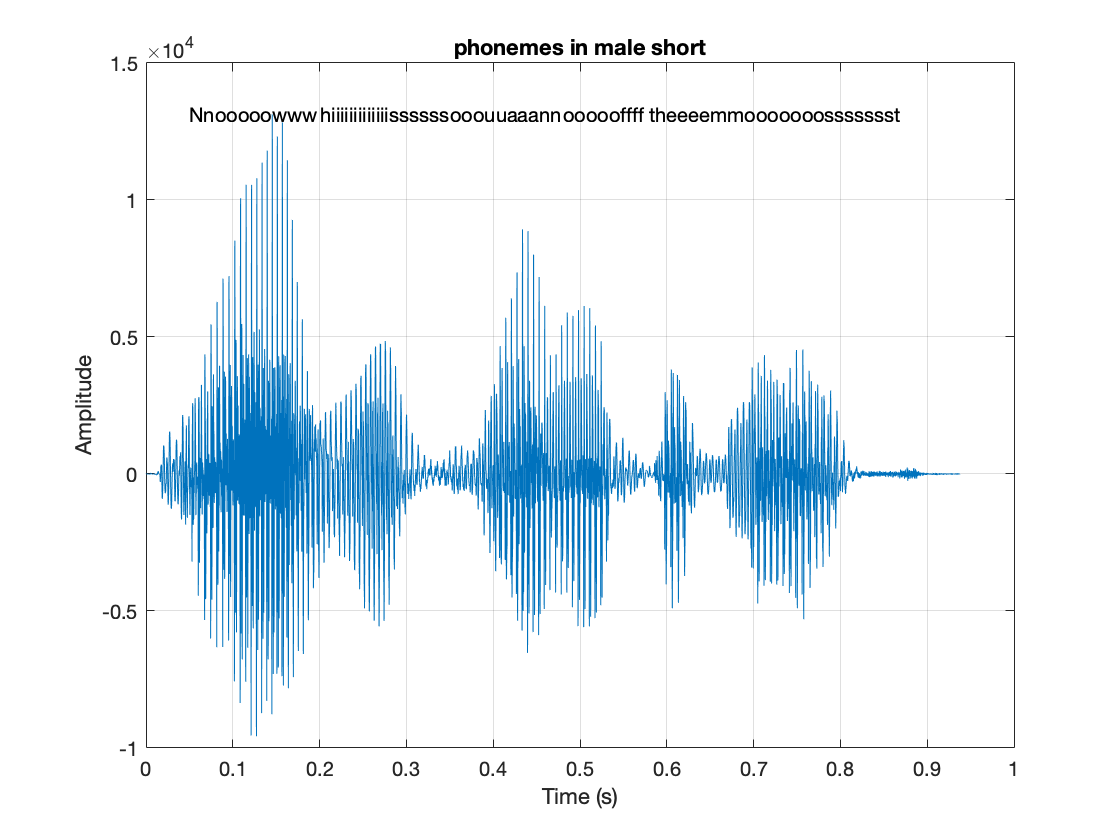

clear all;
close all;
load assignment1.mat;

%[5.1]
Fs = 8000;
time = 0:1/Fs:size(male_short,1)/Fs - 1/Fs;

% We can identify the other phonemes by analyse the spectrum of each frames
% The position of the formants allow us to determine the phonemes

plot(time, male_short);
grid on; xlabel('Time (s)'); ylabel('Amplitude');
title('phonemes in male short')

xt = [0.05 0.2 0.35 0.48 0.58 0.65];
yt = [max(male_short) max(male_short) max(male_short) max(male_short) max(male_short) max(male_short)];
str = {'Nnooooowww','hiiiiiiiiiiiiissssss', 'ooouuaaann', 'oooooffff', 'theeee', 'mmooooooossssssst'};
text(xt,yt,str)

% Quote = "Now he is one of the most"

[5.2] Consonnants can be voice sound (b, g, p, m, ...) and can have formant frequency

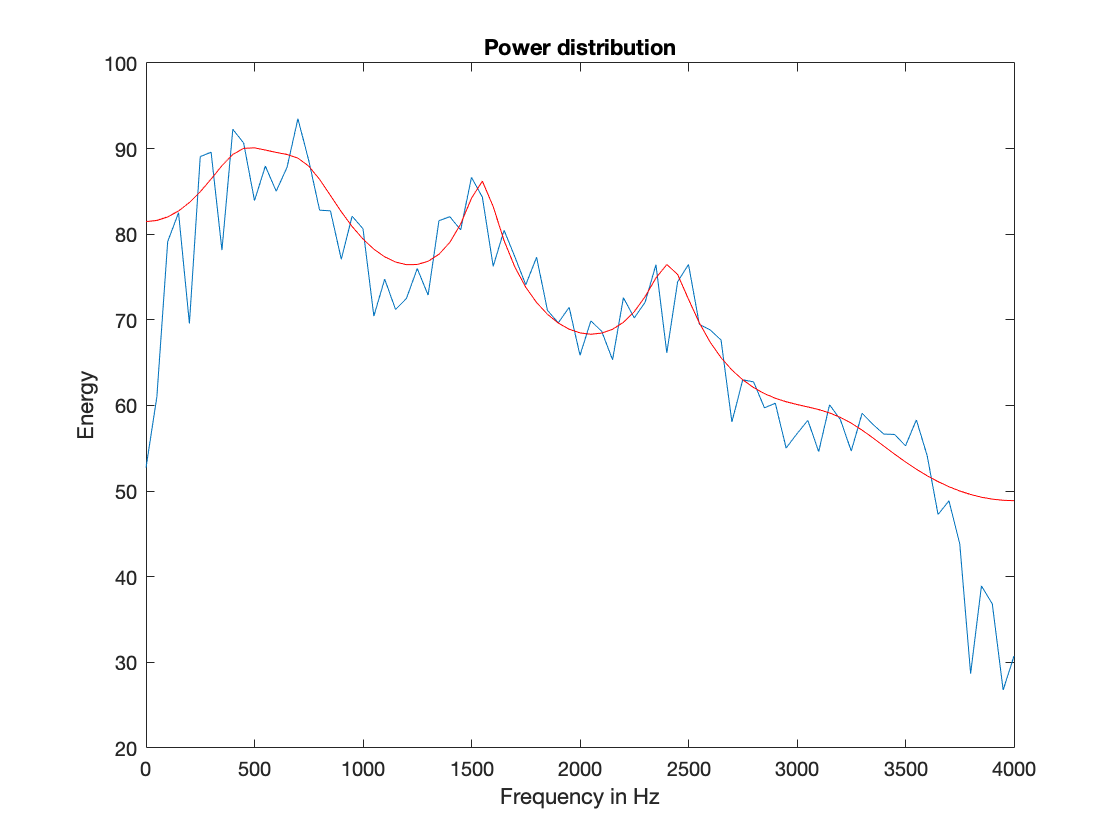

x = male_short; N = length(time(0.05*Fs:0.07*Fs)) - 1; S = 0.05*Fs;
% x is a vector of speech, N is the frame length (must be even)
% S is the first sample of the frame to be analyzed
xf = x(S:S+N-1).*hanning(N);
%xf = x(S:S+N-1).*rectwin(N);
f = Fs*(0:(N/2))/N;
X = fft(xf);

% M is the prediction order
M = 10;
c = xcorr(xf, xf, M);
[a, e]= levinson(c(M+1:2*M+1)); % a is a vector always starting with a 1.
a = a(:); % Make a a column vector
% The commented code below is essentially equivalent to the twolines above
% r = c(M+1:2*M+1);
% R = toeplitz(r(1:M),r(1:M)); % A Toeplitz matrix with first row r(1:M)
% a = - R / r(2:M+1);
% a = [1; a]; % Add the leading 1
% e = sum(a*r);
h = zeros(N,1);
for k=0:N-1
    h(k+1) = 1 / (a'*exp(-1i*2*pi*k/N*(0:M)') );
end
% h = freqz(1, a, N, ’whole’); % Equivalent to the above for-loop! hold on

figure(1); clf;
plot(f, 10*log10(abs(X(1:N/2+1)).^2)); hold on;
plot(f, 10*log10(e*abs(h(1:N/2+1)).^2), 'r');
title('Power distribution'); xlabel('Frequency in Hz'); ylabel('Energy');

soundsc(male_short(0.05*Fs:0.07*Fs), Fs); % Consonant "n"

[5.3]  A diphtong is a sound formed by the combination of two vowels in a single syllable, in which the sound begins as one vowel and moves towards another (as in *coin*, *loud*, and *side* ).

[5.4] There are 44 phonemes in English

[5.5]     Phone :  any distinct speech sound or gesture, regardless of whether the exact sound is critical to the meanings of words.

            Allophone : any of the various phonetic realizations of a phoneme in a language, which do not contribute to distinctions of meaning. For example, in English an aspirated *p* (as in *pin* ) and unaspirated *p* (as in *spin* ) are allophones of p.

%Part 6

clear all
close all;
load assignment1.mat;

# 6. The Spectogram

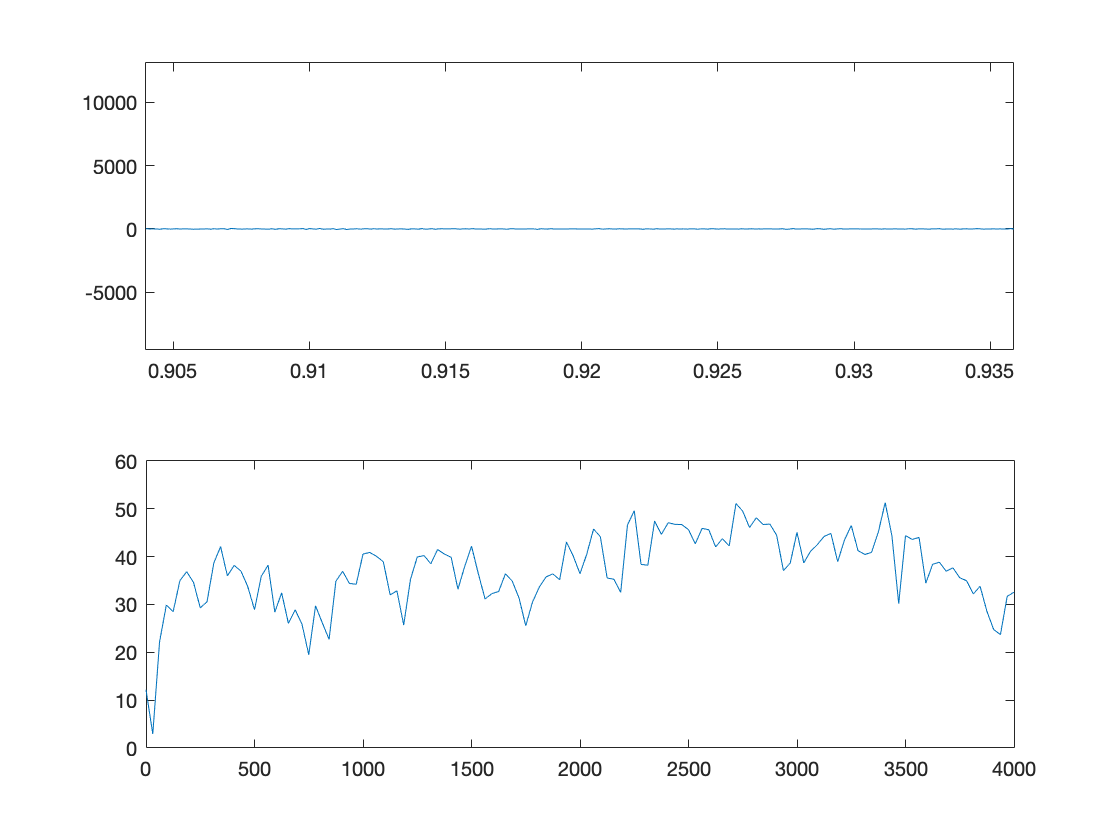

%[6.1] and [6.2]
figure(1)
myspectrogram(male_short, 256, 32); %launch it from the command window to see the animation

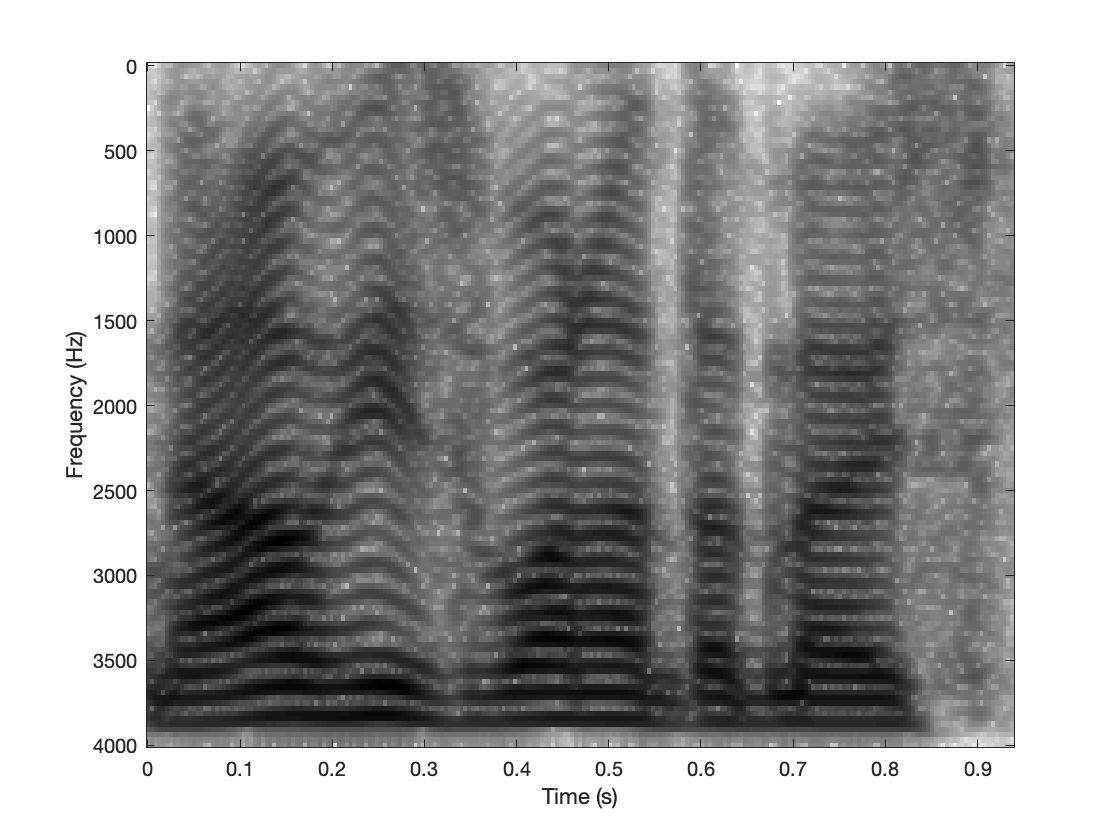


%[6.3]
figure(2)
plotmyspectrogram(male_short, 256, 32); %The Y-axis should be inversed

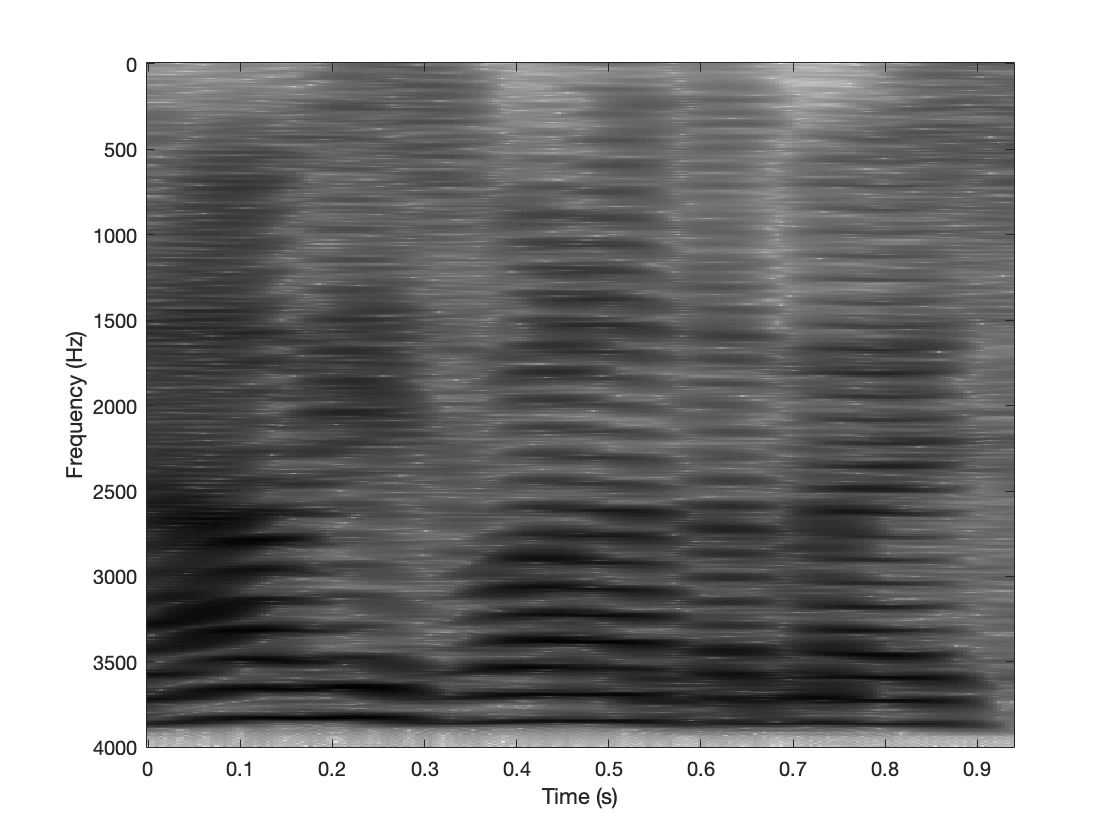

%[6.4] Narrow-band spectogram = fine frequency analysis -> alen is large
figure(3)
plotmyspectrogram(male_short, 1024, 32); %The Y-axis should be inversed

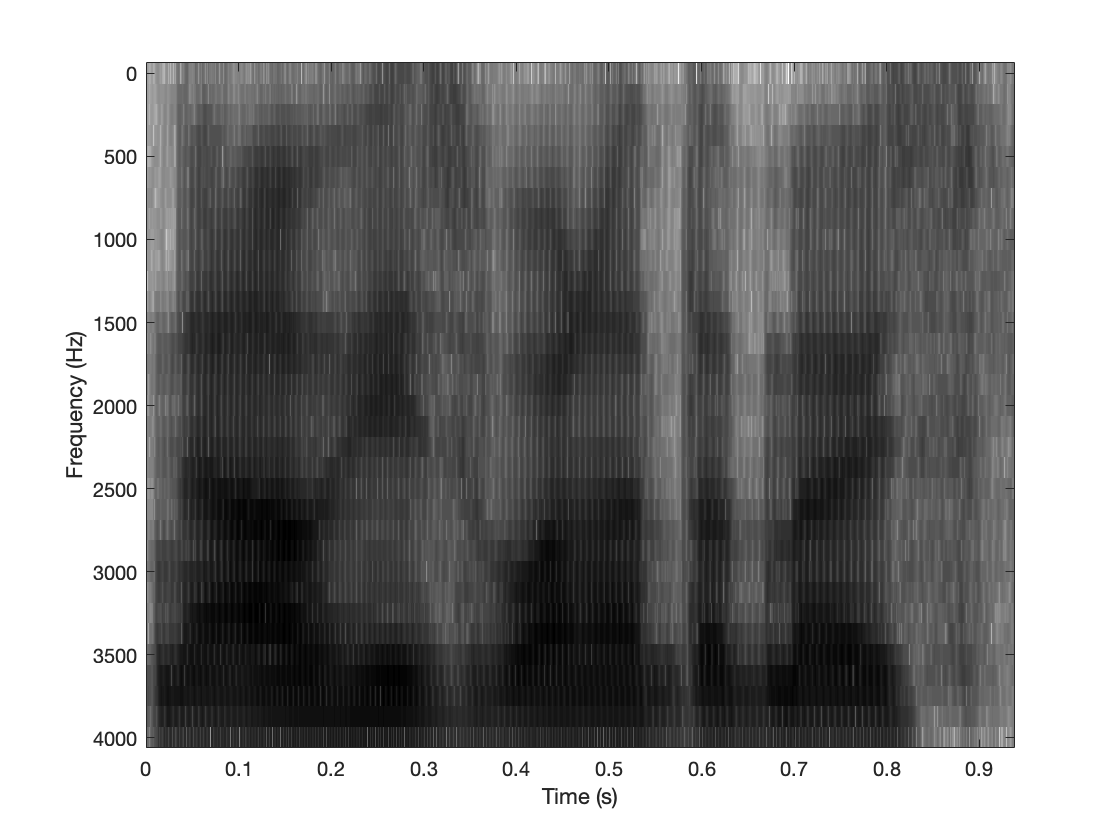

%[6.5] Wide-band spectogram = fine time analysis -> alen is small
figure(4)
plotmyspectrogram(male_short, 64, 1); %The Y-axis should be inversed

% We have blocks in the spectogram we have to smooth.

% Part 7

clear all
close all;
load assignment1.mat;

Fs = 8000;
time = 0:1/Fs:size(male_short,1)/Fs - 1/Fs;

# 7. Speech Parameter Estimation 

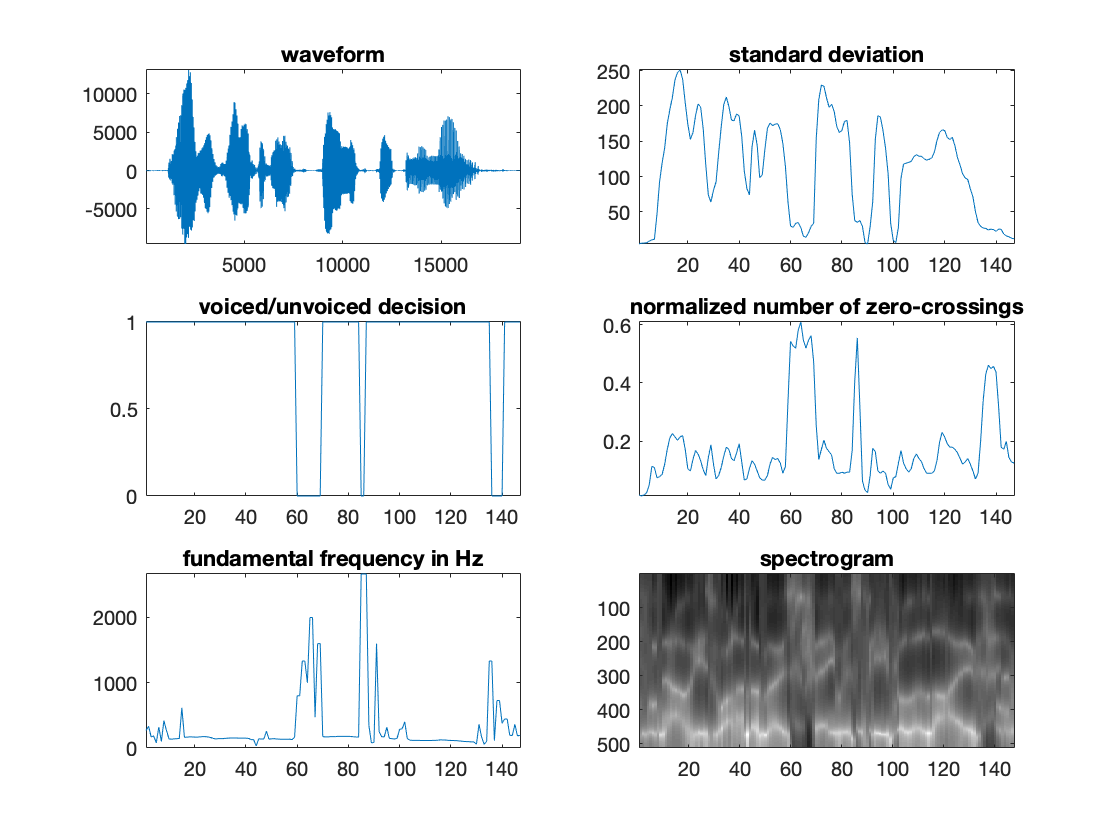

%[7.1] and [7.2] and [7.3]
[E, ZC, V, A, P] = analysis(male_long, 256, 128, 10);

[7.6] The voice/unvoice detection can go wrong if the sound is not clear. We can see that we don't detect the silences in the voice/unvoice detection.

[7.7] A pitch doubling can be cause if a harmonique is interpreted as the fundamental (it can happen if the fundamental power is really low). The same interpretation can be done for pitch halving.

% Part 8 -> Run part 7 first to obtain the parameters {E, ZC, V, A, P, ulen}
ulen = 128;
P = medfilt1(P);

# 8. The Vocoder

%[8.1]
s1 = synthesis1(E, ZC, V, A, P, ulen);
soundsc(s1);
pause(2.5)
%audiowrite(char("synthesis_1.wav"),s1/max(s1),Fs);

We have a very robotic voice

%[8.2]
s2 = synthesis2(E, ZC, V, A, P, ulen);
soundsc(s2);
pause(2.5)
%audiowrite(char("synthesis_2.wav"),s2/max(s2),Fs);

The voice is still robotic but the voice is more intelligible

%[8.3]
s3 = synthesis3(E, ZC, V, A, P, ulen);
soundsc(s3);
pause(2.5)
%audiowrite(char("synthesis_3.wav"),s3/max(s3),Fs);

The intelligibility is not improved. The vocoder assumes that all speech sounds are either voiced or unvoiced.

%[8.4]
s4 = synthesis4(E, ZC, V, A, P, ulen);
soundsc(s4);
pause(2.5)
%audiowrite(char("synthesis_4.wav"),s4/max(s4),Fs);

save('synthesis4.mat','s4')